# HW4

# Name - Vinay Patil

# NetId - vpatil3

# Question 1

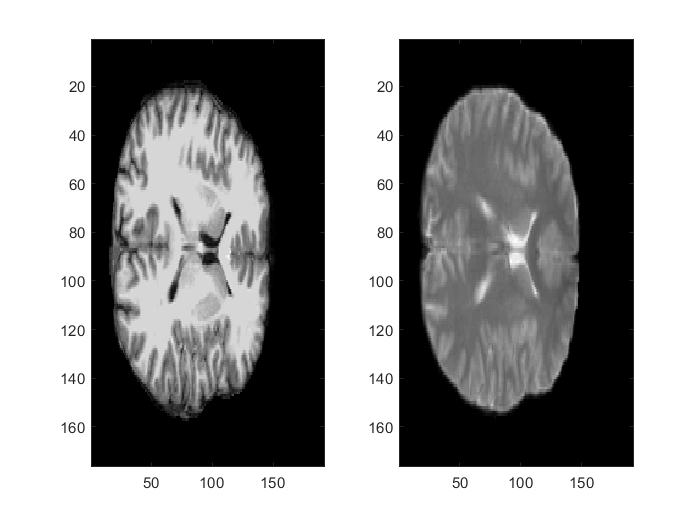

path = 'T_files';
% data (slice of MRI data: T1 structural image of brain)
load(sprintf('%s/T1.mat',path));

% Same, but a T2 image
load(sprintf('%s/T2.mat',path));

% The two images
figure
subplot(1, 2, 1)
imagesc(T1); colormap('gray')
subplot(1,2,2)
imagesc(T2); colormap('gray')

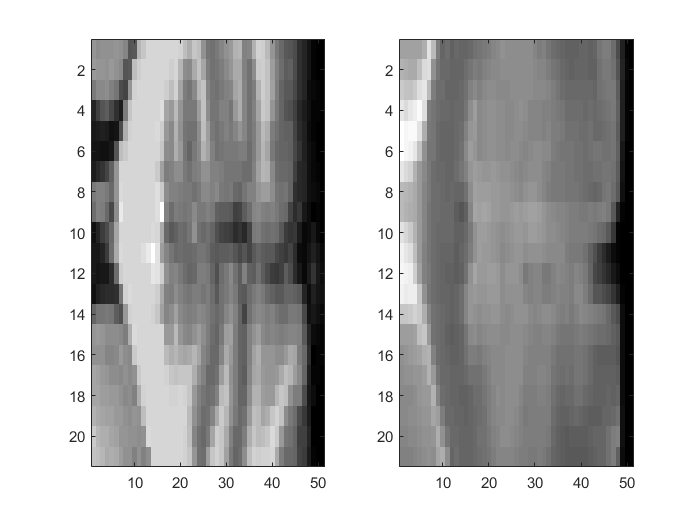



% To save time, just using a small section of data for illustration
T1_section = double(T1(80:100, 100:150));
T2_section = double(T2(80:100, 100:150));

figure
subplot(1, 2, 1)
imagesc(T1_section); colormap('gray')
subplot(1,2,2)
imagesc(T2_section); colormap('gray')

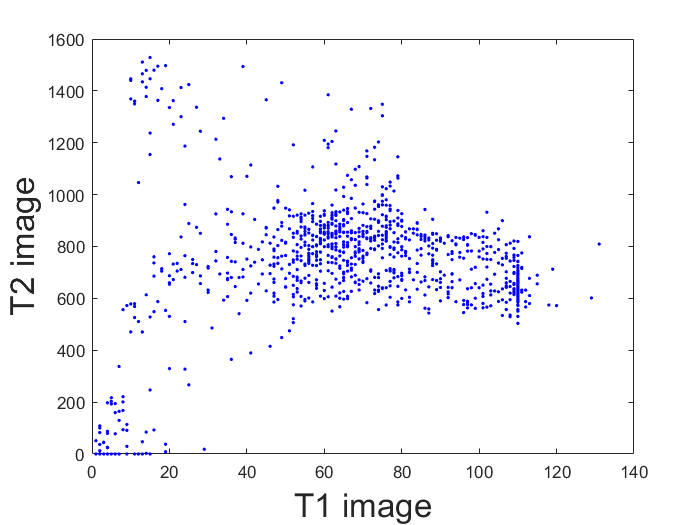


% plot the intensity values against each other
figure
plot(T1_section, T2_section, 'b.')
xlabel('T1 image', 'Fontsize', 20)
ylabel('T2 image', 'Fontsize', 20)

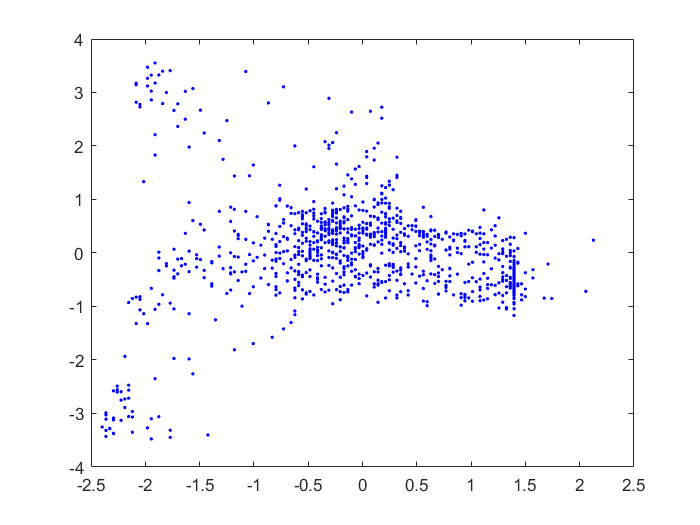



% put data in vector and remove 0 (0 is background) - Means data isn't
% available in voxels
keep = T1_section>0 & T2_section>0;
T1_vec = T1_section(keep);
T2_vec = T2_section(keep);

% rescale (To make it use equally)
T1_vec = (T1_vec-mean(T1_vec))/std(T1_vec);
T2_vec = (T2_vec-mean(T2_vec))/std(T2_vec);

figure
plot(T1_vec, T2_vec, 'b.')

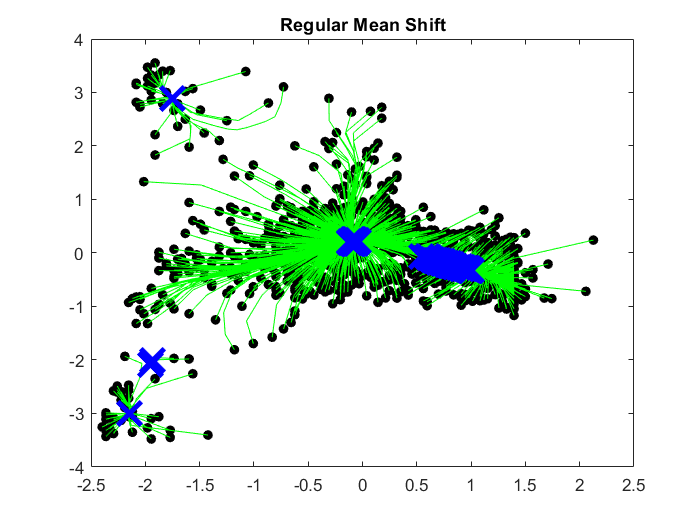

% Setting h=1 as per the question specification
h = 1;

%I have created the meanShift function for reusability, which can be found at the bottom of this script.


%Trial 1
% First I will run the standard mean shift. Which is equivalent to setting e = 0.
% Which will intern set the small circle radius to zero
e = 0;
[seg_feat1,seg_feat2,seg_vec] = meanShift(h,e,T1_vec,T2_vec);
plot(seg_feat1, seg_feat2, 'bluex','markersize', 20, 'linewidth', 3)
title("Regular Mean Shift")
hold off

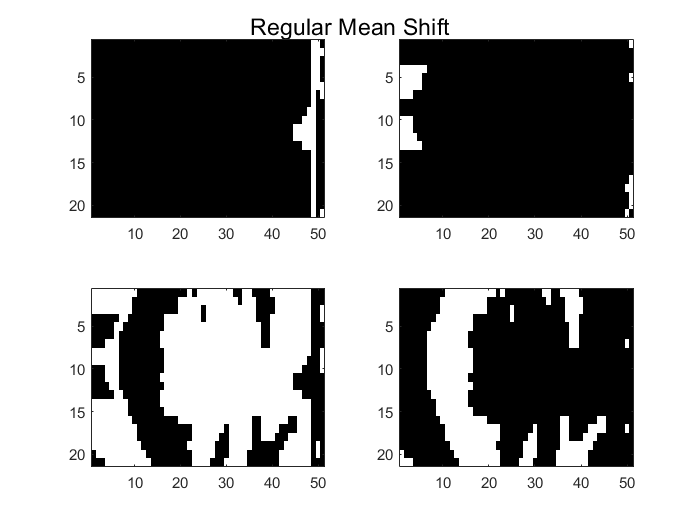

seg_img = T1_section;
seg_img(keep==1) = seg_vec;

figure
suptitle("Regular Mean Shift")
subplot(2,2,1)
imagesc(seg_img==1); colormap('gray')
subplot(2,2,2)
imagesc(seg_img==2); colormap('gray')
subplot(2,2,3)
imagesc(seg_img==3); colormap('gray')
subplot(2,2,4)
imagesc(seg_img==4); colormap('gray')

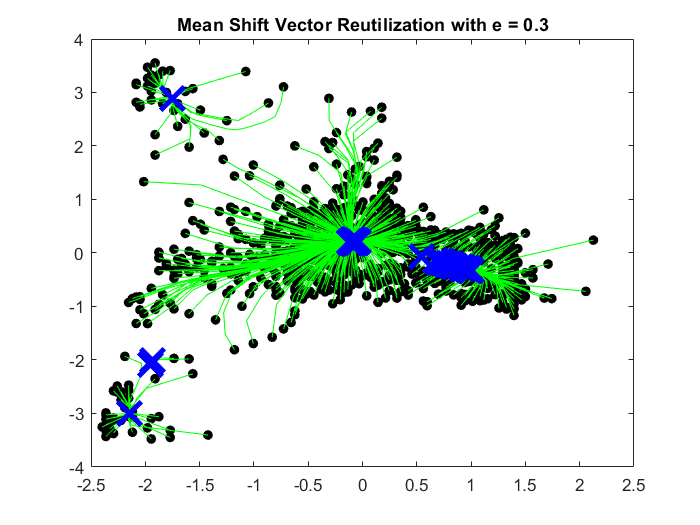


%Trial 2
% Mean Shift Vector Reutilization using e = 0.3 
e = 0.3;
[seg_feat1,seg_feat2,seg_vec] = meanShift(h,e,T1_vec,T2_vec);
plot(seg_feat1, seg_feat2, 'bluex','markersize', 20, 'linewidth', 3)
title("Mean Shift Vector Reutilization with e = 0.3")
hold off

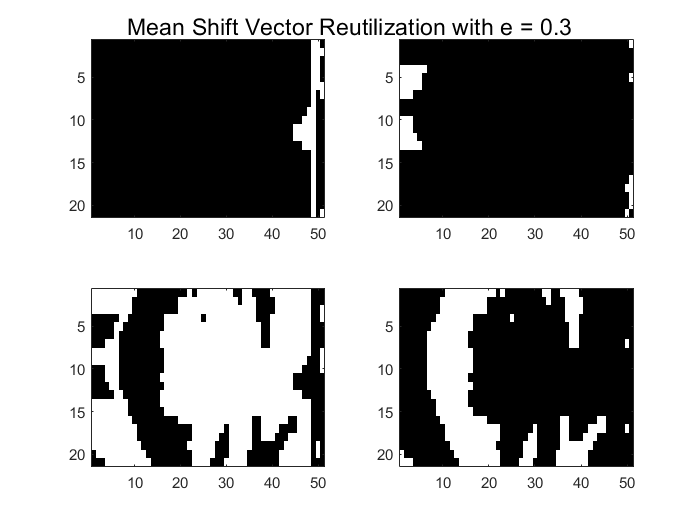


seg_img = T1_section;
seg_img(keep==1) = seg_vec;

figure
suptitle("Mean Shift Vector Reutilization with e = 0.3")
subplot(2,2,1)
imagesc(seg_img==1); colormap('gray')
subplot(2,2,2)
imagesc(seg_img==2); colormap('gray')
subplot(2,2,3)
imagesc(seg_img==3); colormap('gray')
subplot(2,2,4)
imagesc(seg_img==4); colormap('gray')

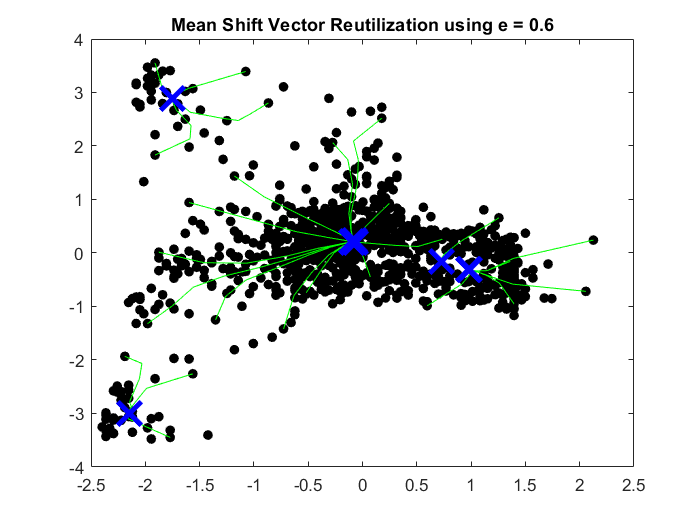


%Trial 3
% Mean Shift Vector Reutilization using e = 0.6
e = 0.6;
[seg_feat1,seg_feat2,seg_vec] = meanShift(h,e,T1_vec,T2_vec);
plot(seg_feat1, seg_feat2, 'bluex','markersize', 20, 'linewidth', 3)
title("Mean Shift Vector Reutilization using e = 0.6")
hold off

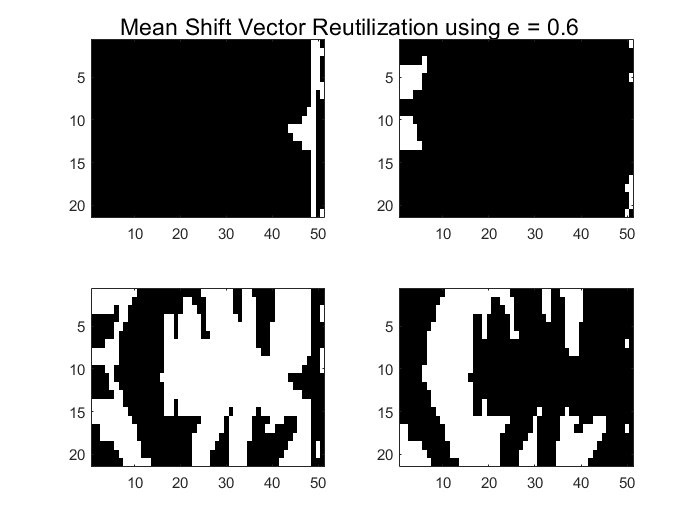


seg_img = T1_section;
seg_img(keep==1) = seg_vec;

figure
suptitle("Mean Shift Vector Reutilization using e = 0.6")
subplot(2,2,1)
imagesc(seg_img==1); colormap('gray')
subplot(2,2,2)
imagesc(seg_img==2); colormap('gray')
subplot(2,2,3)
imagesc(seg_img==3); colormap('gray')
subplot(2,2,4)
imagesc(seg_img==4); colormap('gray')

**Looking at the results of the segmentation for the speedup implementaion using e = 0.3 and e = 0.6, we can say that the results are quite similar to the regular method, with a little increase in error at the edges of the segments in both of them. The error/difference in the segmentation is so minute that its almost not noticible and hence I think the speed up which reduces the time of execution by more than half is worthwile. The reason for the minor difference would be because of the fact that a point at the boundary of 2 segements, may get assigned to either of them, depending on which was the path it fell on at last. **

function [seg_feat1,seg_feat2,seg_vec] = meanShift(radius,eValue,T1_vec,T2_vec)

% Defining the stopping criteria. i.e. Largest distance allowed between 2 iterations without stopping
stop_criterion = .05;

%Computing the small circle radius
eh = eValue*radius;

seg_feat1 = 0*T1_vec;
seg_feat2 = 0*T2_vec;

figure
plot(T1_vec, T2_vec, 'black.', 'markersize', 20)
hold on

%To keep track of points that have already been visited
notVisited = ones(1,length(T1_vec));

%Helper vector
vectorIndices = 1:length(T1_vec);
% Loop through each voxel
for loc=1:length(T1_vec)
    if(notVisited(loc)==1)
        
        
        %Initializing Vector to keep track of all the points that fall within the inner circle as the
        %point at position loc moves
        pointsOnPath = loc;
        
        cur_feat1 = T1_vec(loc);
        cur_feat2 = T2_vec(loc);
        cur_criterion = 10;
        % Find the convergence point for the single voxel
        while cur_criterion>stop_criterion
            % compute distance for all points vs first (Euclidian Distance)
            dist_loop = ((cur_feat1(end) - T1_vec).^2 + (cur_feat2(end) - T2_vec).^2).^.5;
            keep_loop = dist_loop<radius; % Filtering to check which are within the ball of radius 1
            
            %Logical vector for the points which fall within inner circle of radius eh
            inner_circle_pts = dist_loop<eh;
            %Getting indices from the above logical vector and appending it to the pointsOnPath vector
            pointsOnPath = [pointsOnPath, vectorIndices(inner_circle_pts)];
            
            mean_loop_feat1 = mean(T1_vec(keep_loop==1));
            mean_loop_feat2 = mean(T2_vec(keep_loop==1));
            cur_criterion = ((cur_feat1(end) - mean_loop_feat1).^2 + (cur_feat2(end) - mean_loop_feat2).^2).^.5;
            cur_feat1 = [cur_feat1, mean_loop_feat1];
            cur_feat2 = [cur_feat2, mean_loop_feat2];
        end
        plot(cur_feat1, cur_feat2, 'green-')
        seg_feat1(pointsOnPath) = cur_feat1(end);
        seg_feat2(pointsOnPath) = cur_feat2(end);
        
        %Setting the points as visited, so that they are skipped in the iteration
        notVisited(pointsOnPath) = 0;
    end
end


% Round and look at unique end points.
unique_vals = unique([round(seg_feat1), round(seg_feat2)], 'rows');

% Looking at the unique end points, the below values work great for all 3 trails considered
seg_vec = 0*T1_vec;
seg_vec(round(seg_feat1)==-2 & round(seg_feat2)== -3) = 1;
seg_vec(round(seg_feat1)==-2 & round(seg_feat2)== -2) = 1;
seg_vec(round(seg_feat1)==-2 & round(seg_feat2)== 3) = 2;
seg_vec(round(seg_feat1)==0 & round(seg_feat2)== 0) = 3;
seg_vec(round(seg_feat1)==1 & round(seg_feat2)== 0) = 4;


end